Create a transfer function for testing

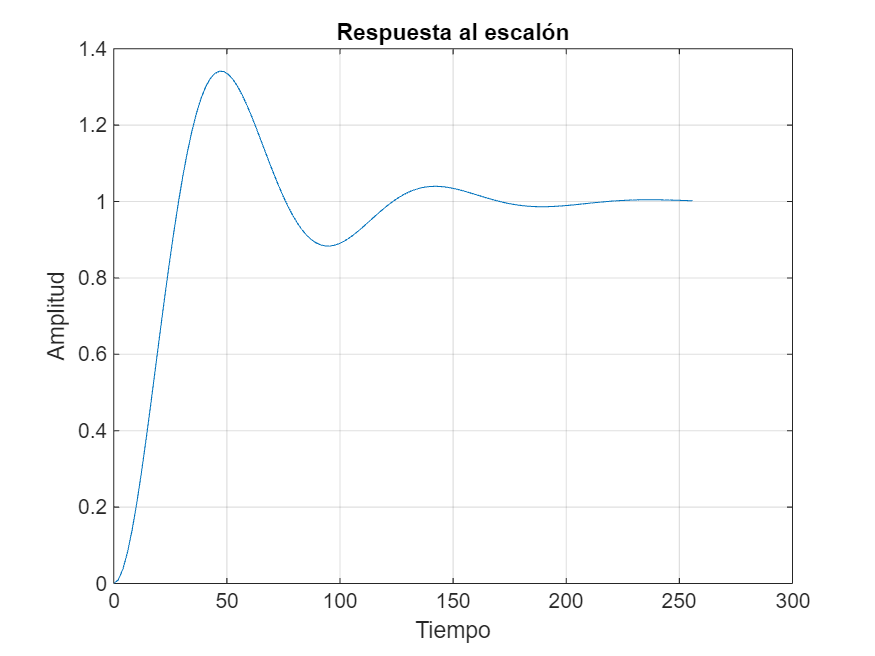

% Definir los parámetros del sistema
%wn = 2.0;  % frecuencia natural
%zeta = 0.35;  % factor de amortiguamiento
wn = rand(1,1);  % frecuencia natural
zeta = rand(1,1);  % factor de amortiguamie

% Crear la función de transferencia
num = [wn^2];
den = [1, 2*zeta*wn, wn^2];
%num = [1]; % Coeficientes del numerador (en este caso solo 1)
%den = [1, -2]; % Coeficientes del denominador, incluyendo un polo con parte real positiva

system = tf(num, den);

% Generar la respuesta al escalón
[y, t] = step(system);

% Graficar la respuesta al escalón
figure;
plot(t, y);
title('Respuesta al escalón');
xlabel('Tiempo');
ylabel('Amplitud');
grid on;

Calcular settlement time

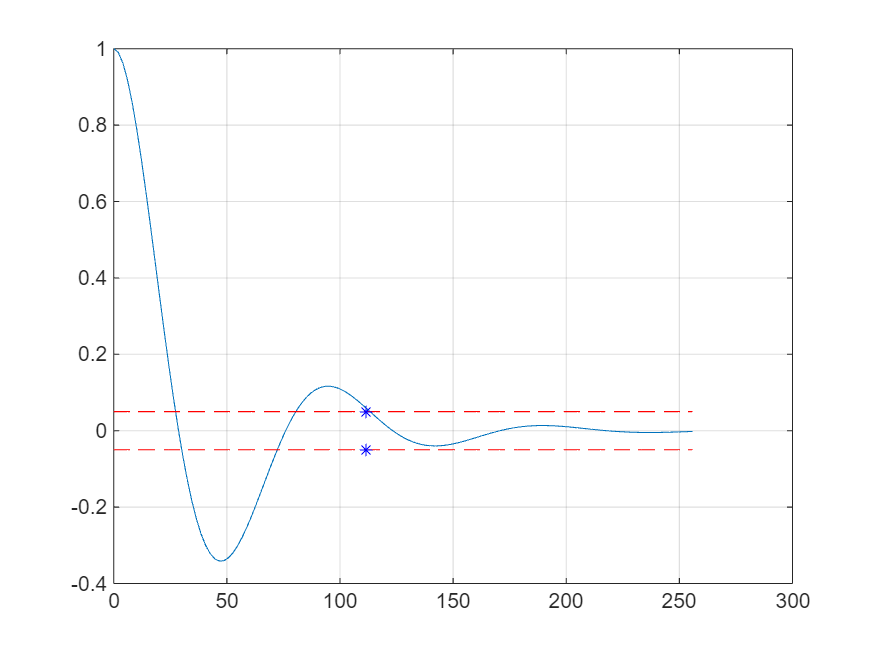

setpoint = 1;
tol      = 5/100; % 5%
ts1 = calculateSettlementTime(setpoint, y, t, tol);
bounds = [-tol tol];
e = setpoint-y;
figure()
plot(t,e); hold on;
plot(t,bounds(1)*ones(1,length(t)),'r--');
plot(t,bounds(2)*ones(1,length(t)),'r--');
plot(ts1,bounds(2),'b*'); plot(ts1,bounds(1),'b*')
grid on;

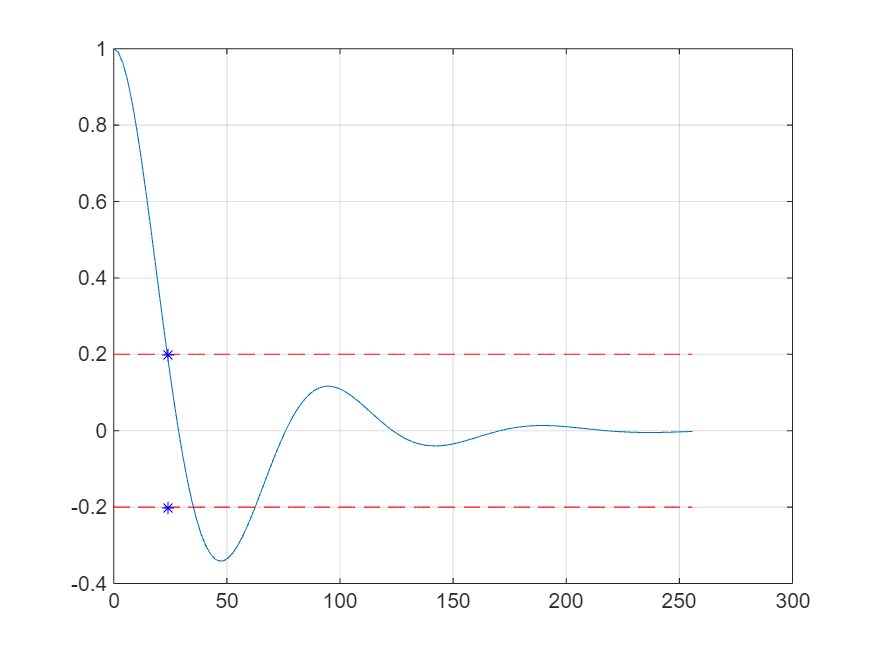

figure()
tol = 1-(80/100);
boundsris = [-tol tol];
tr = calculateRissingTime(setpoint, y, t, tol);
figure()
plot(t,e); hold on;
plot(t,boundsris(1)*ones(1,length(t)),'r--');
plot(t,boundsris(2)*ones(1,length(t)),'r--');
%plot(t(x),e(x),'*')
plot(tr,boundsris(2),'b*'); plot(tr,boundsris(1),'b*')
grid on;

Calculate overshoot

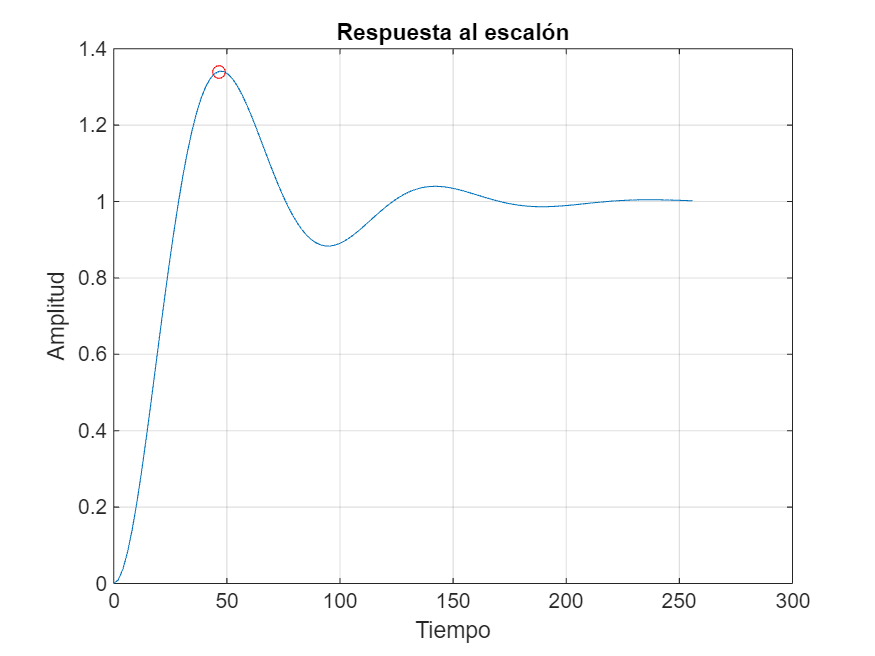

[overshoot,to] = calculateOvershoot(y);
%times = t(3);

% Graficar la respuesta al escalón
figure;
plot(t, y); hold on;
plot(t(to),overshoot,'ro');
title('Respuesta al escalón');
xlabel('Tiempo');
ylabel('Amplitud');
grid on;

For a MIMO system

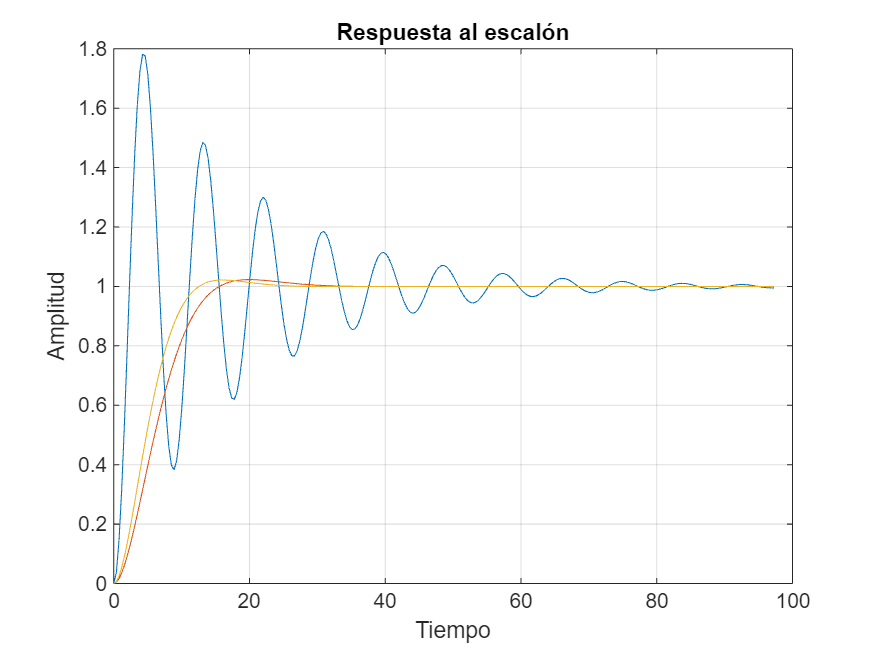

% Definir los parámetros del sistema
wn1 = rand(1,1);  % frecuencia natural
zeta1 = rand(1,1);  % factor de amortiguamie

wn2 = rand(1,1);  % frecuencia natural
zeta2 = rand(1,1);  % factor de amortiguamie

wn3 = rand(1,1);  % frecuencia natural
zeta3 = rand(1,1);  % factor de amortiguamie

% Crear la función de transferencia 1
num1 = [wn1^2];
den1 = [1, 2*zeta1*wn1, wn1^2];

% Crear la función de transferencia 1
num2 = [wn2^2];
den2 = [1, 2*zeta2*wn2, wn2^2];

% Crear la función de transferencia 1
num3 = [wn3^2];
den3 = [1, 2*zeta3*wn3, wn3^2];

system1 = tf(num1, den1);
system2 = tf(num2, den2);
system3 = tf(num3, den3);

G = [system1;system2;system3];

% Generar la respuesta al escalón
[y, t] = step(G);

% Graficar la respuesta al escalón
figure;
plot(t, y);
title('Respuesta al escalón');
xlabel('Tiempo');
ylabel('Amplitud');
grid on;

Calcular settlement time

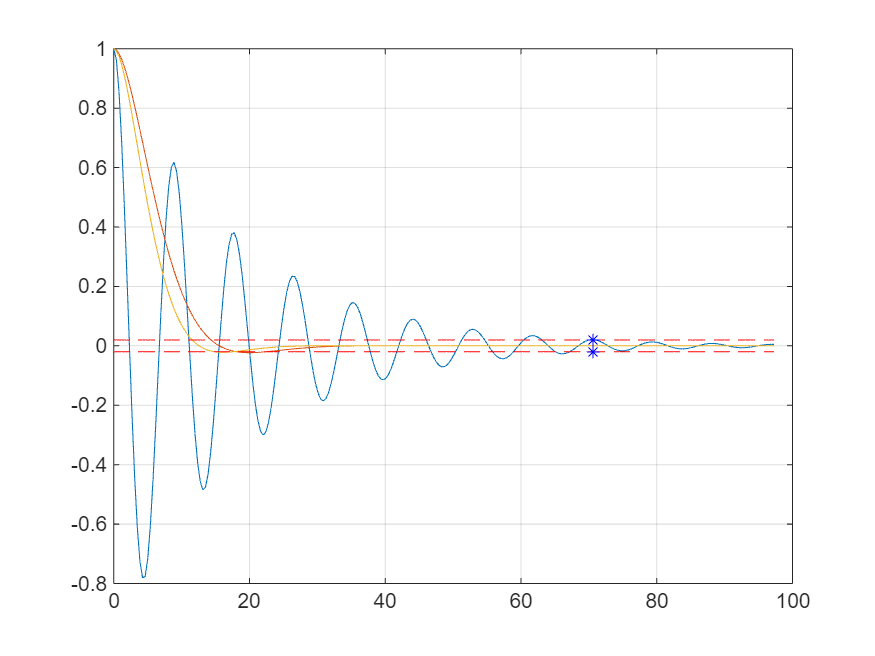

setpoint = 1;
tol      = 2/100; % 5%
ts = calculateSettlementTime(setpoint, y, t, tol);
%%%Calculate error
e = setpoint-y;
bounds = [-tol tol];
%%%find index out the frange
[x,y] = find(~(e<bounds(2) & e>bounds(1)));

figure()
plot(t,e); hold on;
plot(t,bounds(1)*ones(1,length(t)),'r--');
plot(t,bounds(2)*ones(1,length(t)),'r--');
%plot(t(),e(x,y),'go');
plot(ts,bounds(2),'b*'); plot(ts,bounds(1),'b*')
grid on;

function ts = calculateSettlementTime(setpoint, y, t, tol) 
    %%%Calculate error
    e = setpoint-y;
    %%%Set bounds
    bounds = [-tol tol];
    %%%find index out the frange
    [x,~] = find(~(e<bounds(2) & e>bounds(1)));
    if(x(end)==length(t))
        ts=NaN;
    else
        %%%find the last index out the frange
        ts = t(max(x));
    end
end

function tr = calculateRissingTime(setpoint, y, t, rising)
    %%%Calculate error
    e = setpoint-y;
    boundsris = [-rising rising];
    %%%find index out the frange
    [x,~] = find((e<=boundsris(2) & e>=boundsris(1)));
    tr = t(min(x));
end

function [overshoot,to] = calculateOvershoot(y)
    [overshoot,to] = max(y);
end